# Import Data from Text File to Table

If your text file has tabular data, you can import the data as a table using the `readtable` function. A table consists of column-oriented variables, each containing data of the same type. Variables in a table can hold different data types and sizes, but each variable must have the same number of rows. 

`readtable` detects elements of your input file to determine how best to import the contents the input file. `readtable` analyzes the format of your data based on delimiters, number of header lines, number of variables, types of variables, and metadata of the first 250 nonempty lines of data. You can customize aspects of the import using name-value arguments or an import options object.

## Read Text File as Table

You can import tabular data from a text file into a table using the `readtable` function. For example, the sample file `outages.csv` contains comma-separated column-oriented data.  

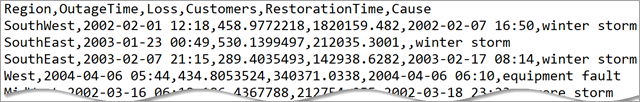

Create a table from `outages.csv`. The resulting table contains one variable for each column in the file, and `readtable` treats the entries in the first line of the file as variable names. Display the first three rows and first five columns of the table using indexing.

T = readtable("outages.csv");
T(1:3,1:6)

## Specify Delimiters

By default, `readtable` detects the file delimiter and uses it to split your data into table elements. `readtable` determines the delimiter by using the number of variables and the consistency of data type in columns in the first 250 nonempty lines of data. For example, because `airlinesmall.csv` contains comma-separated data, `readtable` detects the delimiter as "`,`" and splits the data accordingly.

T = readtable("airlinesmall.csv");

If `readtable` does not select the delimiter you intended, you can specify the delimiter using the `Delimiter` name-value argument. 

T = readtable("airlinesmall.csv",Delimiter=",");

## Read Data with Column Headers

By default, `readtable` determines if your file has a row of headers to use as variable names. For example, the first two rows of the `headersAndMissing.txt` file contain variable names and headers. `readtable` keeps the first row of variable names and discards the second row of headers.

T = readtable("headersAndMissing.txt");

You can specify the number of header lines to skip at the beginning of the file by using the `NumHeaderLines` name-value argument. For example, specify the first row as a header line to skip before reading data.

T = readtable("headersAndMissing.txt",NumHeaderLines=1)

## Read Data Without Column Headers

If your file does not have column headers, `readtable` assigns default variable names in the format `Var1`, `Var2`, ..., `VarN`. For example, `mySpaceDelimTable.txt` does not have column names in the first row, so `readtable` assigns the default variable names `Var1` to `Var5`. View the first three rows of your table.

T = readtable("mySpaceDelimTable.txt");
head(T,3)

If your file has column headers, but you do not want to read them in, specify the `ReadVariableNames` name-value argument as `false`.

T = readtable("headersAndMissing.txt",ReadVariableNames=false);

## Fill Missing Data

If your file contains missing data, `readtable` fills the data gaps with the appropriate `missing` values. Gaps are considered missing data if they contain only white-space characters or the row ends before a variable is found. For example, in the file `headersAndMissing.txt`, the last two rows have gaps where the previous rows have data values. By default, `readtable` fills these gaps with appropriate missing values, such as `NaN`.

T = readtable("headersAndMissing.txt");

If you want to adjust how `readtable` handles missing data, use the `MissingRule` name-value argument. For example, to omit rows with missing data, specify `MissingRule` as "`omitrow"`.

T = readtable("headersAndMissing.txt",MissingRule="omitrow");

## Convert Date Locale

If your file contains date values in a date locale different from that of your system, `readtable` can convert and import the data values with your preferred date locale. For example, create a table from `outages.csv` by reading the file with a specified character encoding scheme and interpreting the date values using the United States English locale. Specify the character encoding scheme of the file using the `Encoding` name-value argument. Specify the format and locale of the input dates using the `DateLocale` name-value argument. View the first three rows of your table.

T = readtable("outages.csv", ...
    Encoding="ISO-8859-15", ...
    DateLocale="en_US");
head(T,3)

## Read Hexadecimal and Binary Numbers

If your file contains hexadecimal or binary literals, `readtable` can read and store them as numeric variables in a table. The `readtable` function automatically reads hexadecimal and binary numbers when they include the `0x` and `0b` prefixes, respectively. The numeric values are stored using integer data types. You can also use import options to read such numbers when they do not have prefixes.

For example, create a table from the `hexAndBinary.txt` file. `readtable` detects the numbers with `0x` and `0b` prefixes and stores them as integers.

T = readtable("hexAndBinary.txt");

By default, `readtable` uses the smallest unsigned integer class possible to import hexadecimal and binary literals.

To specify the data types for storing the numeric values imported from hexadecimal and binary numbers, use the `HexType` and `BinaryType` name-value arguments. For example, store the values as signed 32-bit integers.

T = readtable("hexAndBinary.txt",HexType="int32",BinaryType="int32");

## Configure Import Using Import Options

To further configure your import, you can use an import options object to control how `readtable` interprets your file. Compared to name-value arguments, an import options object provides more control, better performance, and reusability of the file import configuration. 

The import options object contains properties that store information detected about the input file. You can address specific variables or use dot notation to address all variables. For example, create an import options object from `outages.csv`. View the `VariableNames` property of the import options object, which stores the detected variable names.

opts = detectImportOptions("outages.csv");
opts.VariableNames

To change the data types of specific variables, use the `setvartype` function. For example, change the data type of the `Region` variable to `string`.

opts = setvartype(opts,"Region","string");

To set options for specific variables, use the `setvaropts` function. For example, generate an error if the `RestorationTime` variable has an empty field.

opts = setvaropts(opts,"RestorationTime",EmptyFieldRule="error");

To specify a subset of variables to import, use the `SelectedVariableNames` property. For example, import only the `Region` and `RestorationTime` data.

opts.SelectedVariableNames = ["Region","RestorationTime"];

After you finish configuring your import options object, use it with `readtable` to import your file. 

T = readtable("outages.csv",opts);
head(T,3)

For more information about using an import options object, see [docid:matlab_ref#bvcithw](matlab:open('docid:matlab_ref#bvcithw')).

*Copyright 2018 The MathWorks, Inc.*